# HW 1

## Problem 1

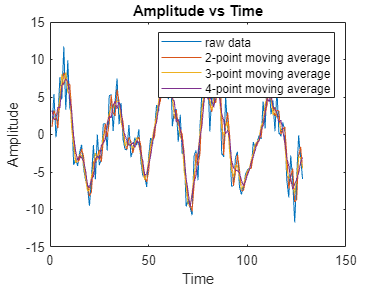

% import data
f = fopen("noisy.txt");
data = textscan(f,'%s');
fclose(f);
noisy = str2double(data{1}(1:1:end));

% smooth data with a moving mean
clean = zeros(128,3); % initialize array for cleaned data
for i = 2:4
    clean(:,i-1) = movmean(noisy,i);
end

% plot the data
plot(noisy); hold on;
plot(clean(:,:)); 
title("Amplitude vs Time"); ylabel("Amplitude"); xlabel("Time");
legend(["raw data", "2-point moving average", "3-point moving average", "4-point moving average"]);
hold off;

## Problem 2

syms t
y = 5*sin(4*t) + 3*cos(4*t)

$$y = 3\,\cos\left(4\,t\right)+5\,\sin\left(4\,t\right)$$

z = rewrite(y,"sin")

$$z = -6\,{\sin\left(2\,t\right)}^{2}+5\,\sin\left(4\,t\right)+3$$

rewrite(z,"cos")

$$ans = 6\,{\cos\left(2\,t\right)}^{2}+5\,\sin\left(4\,t\right)-3$$

## problem 4


syms t
y = 0.0037 + 9.00000e-04.*cos(t)

$$y = \frac{9\,\cos\left(t\right)}{10000}+\frac{37}{10000}$$

figure;
y_hat = fourier(y,t)

$$y\_hat = \frac{9\,\pi \,\left(\delta (t-1)+\delta (t+1)\right)}{10000}+\frac{37\,\pi \,\delta (t)}{5000}$$


time = 1:.1:1000

time = 1.0e+03 *

    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0053    0.0054    0.0055    0.0056    0.0057    0.0058    0.0059


yVal = subs(y,t,time)